## Space Vehicle Validation Script

Load configurations and combine the structs for the SV

% Initialize the model structure
clc; clear all;
% Load and combine the structures
SV = fem.merge_fem_models(config_bus(), config_Iso_Obench(), config_Payload());
% Visualize the combined spacecraft FEM model (optional)
% viz.plot_fem_model(SV);

Simulate disturbances from the RWAs

% Load options profile
% Compute the spacecraft response under reaction-wheel disturbances
sim_time = 3600; fs = 1000; rpm_start = 1900;
[options_rwa_disturbances, srp_info] = options_rwa_dist(sim_time, fs, rpm_start)

options_rwa_disturbances = struct with fields:
         t: [0 1.0000e-03 0.0020 0.0030 0.0040 0.0050 0.0060 0.0070 0.0080 0.0090 0.0100 0.0110 0.0120 0.0130 0.0140 0.0150 0.0160 0.0170 0.0180 0.0190 0.0200 0.0210 0.0220 0.0230 0.0240 0.0250 0.0260 0.0270 0.0280 0.0290 0.0300 … ] (1×3600001 double)
    forces: [1×4 struct]


srp_info = struct with fields:
                  M_total: 7.7669e+03
                  I_total: 2.7894e+05
                     x_cg: -2.9275e-17
             x_centerline: 0
             width_bottom: 16
                 A_bottom: 32
                lever_arm: 1
                    F_srp: 2.0338e-04
                    T_srp: 2.0338e-04
    alpha_sv_uncontrolled: 7.2912e-10
                 num_rwas: 2
                  T_wheel: -1.0169e-04
              alpha_wheel: -5.0846e-04
                rpm_start: 1900
                  rpm_end: 1.8825e+03
                delta_rpm: -17.4795


% [X_rms_rwa_dist, X_rwa_dist] = fem.calculate_rms(SV, options_rwa_disturbances);
[X_rms_rwa_dist, X_rwa_dist] = fem.numeric_sim(SV, options_rwa_disturbances);

Plot the response of the system to the disturbance

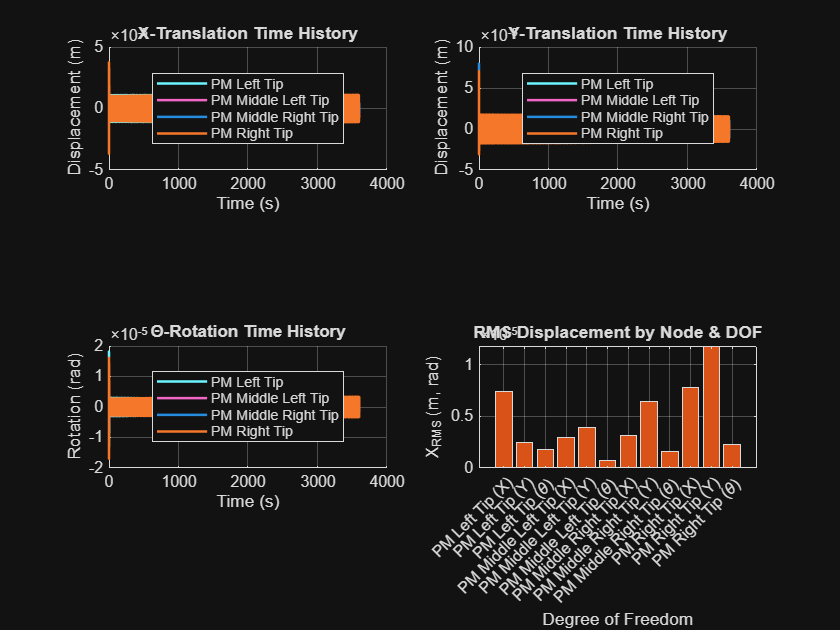

% Start with the response of the primary mirrors
options_plot_ids_PM = {"PM Left Tip", "PM Middle Left Tip", "PM Middle Right Tip", "PM Right Tip"};
viz.plot_rms(SV,options_rwa_disturbances,X_rwa_dist,X_rms_rwa_dist,options_plot_ids_PM);

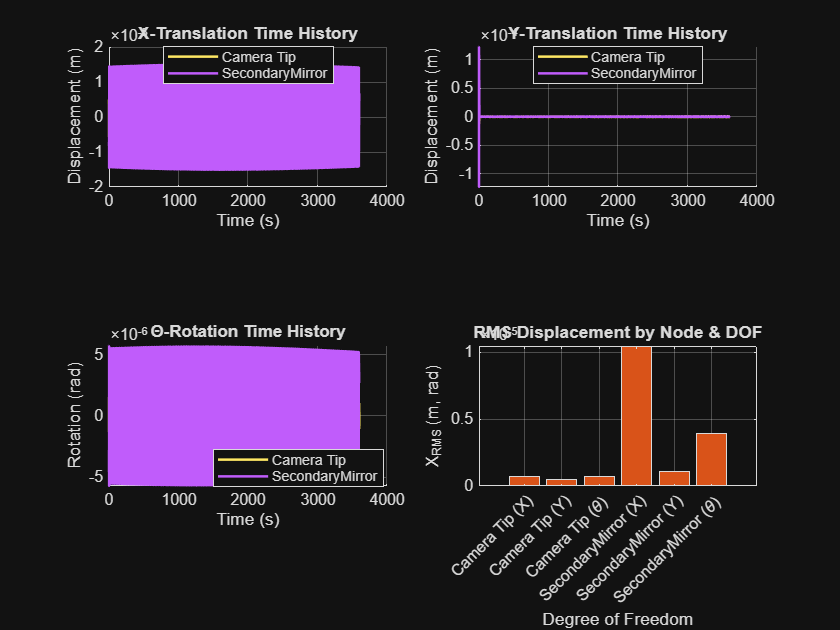

% Next evaluate the response of the secondary mirror and camera
options_plot_ids_SM_Cam = {"SecondaryMirror", "Camera Tip"};
viz.plot_rms(SV,options_rwa_disturbances,X_rwa_dist,X_rms_rwa_dist,options_plot_ids_SM_Cam);

Calculate pointing error of the mirrors

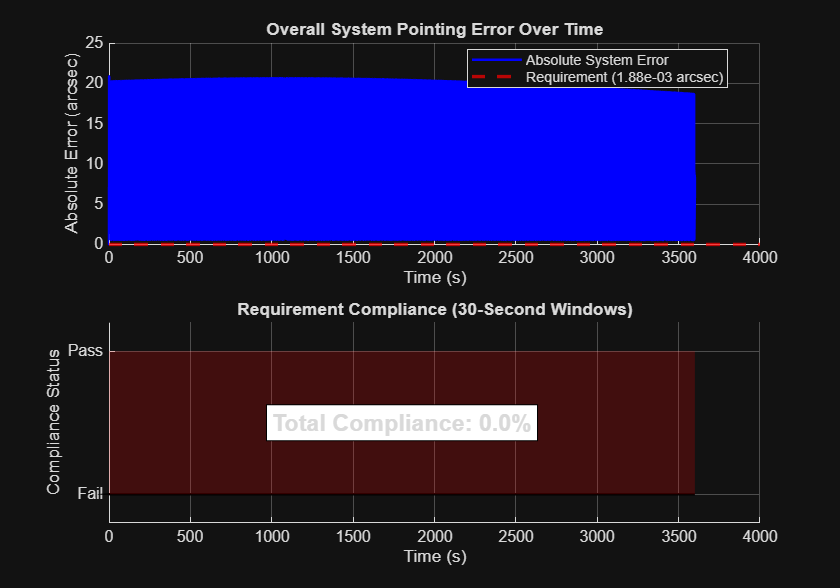

% Establish optical nodes
optical_nodes.sm_id = "SecondaryMirror";
optical_nodes.pm_ids = {"PM Left Tip", "PM Middle Left Tip", "PM Middle Right Tip", "PM Right Tip"};
[pointing_error, components] = fem.calculate_optical_pointing_error(SV, X_rwa_dist, optical_nodes);
threshold = 1.88e-3; window_size = 30;
viz.plot_pointing_error_requirement(options_rwa_disturbances.t, pointing_error, threshold, window_size)

Secondary Mirror Disturbance Analysis: Build State Space

% Define damping and motor disturbance
zeta = 0.2;
options_sm_motor = options_sm_motor();
% Call helper function to generate SS matrecies
[A, B, C, D] = fem.build_state_space(SV, options_sm_motor, optical_nodes, zeta);

Compute PSD Response of the System

% Define range of frequencies
f_range = linspace(10, 100, 1000)';
rms_error = fem.compute_psd_rms(A, B, C, D, f_range);